# Read ForecastDualKc Outputs Using Matlab

Series of code snippets to read, plot, and analyze output files from FOrecastDualKc. THe code below is aimed at being simple and easy to read, without necesarily being the most elegant or efficient Matlab code. You may want to consider converting some of these snippets into functions to re-use in your data analysis scripts.

#### Read .JSON file

% Read JSON file as a long string
filename = 'example_field_settings_inputs_outputs_ForecastDualKc.json';
text = fileread(filename);

% Decode string into Matlab structure
J = jsondecode(text);


#### Plot all scenarios

This script will simply plot all the data in one figure using random colors for each scenario. THis snippet is useful to quickly look at a specific variable before doing any analysis.

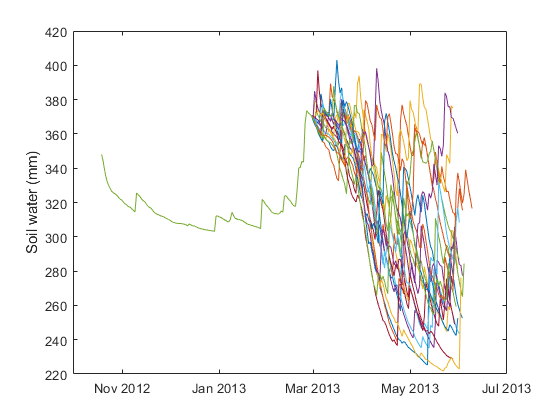

figure('Color','w')
for i=1:length(J.outputs.soilWater)
    plot( datetime(J.outputs.soilWater(i).x), J.outputs.soilWater(i).y );
    hold on
end
ylabel('Soil water (mm)')

#### Reproduce figure in the web interface

A figure that will display scenarios using a light gray color (note that colors are assigned using a scale of 0-1 rather than 0-255) and the median using a distinct red color to show the main trend. To find the scenario containing the median we can check if the word "median" is in the name of the scenario.

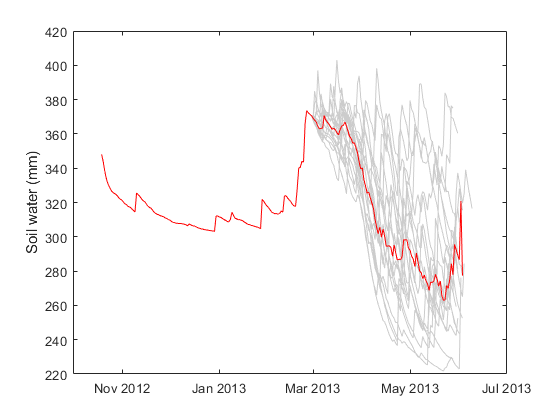

figure('Color','w')
for i=1:length(J.outputs.soilWater)
    plot( datetime(J.outputs.soilWater(i).x), J.outputs.soilWater(i).y, 'LineStyle','-','Color',[0.8,0.8,0.8]);
    hold on
end
plot( datetime(J.stats.soilWater{2}.x), J.stats.soilWater{2}.y, '-r');
ylabel('Soil water (mm)')

#### Compile all the scenarios for a given variable into a single table

Some people may want to have all the scenario in a single table where rows represent days of the growing season and columns each different scenario. At first sight this task seems simple, but the fact that ForecastDualKc uses thermal units to track growing season time creates growing seasons of different lengths in terms of calendar days. To merge all the scenarios we need to do a little bit of work. We first identify the longest scenario, then we create an array of NaNs, and then we fill in the days with observations for each scenario. This way, scenarios that are shorter will have extra days filled with NaNs, which can be easily ignored by many Matlab functions (e.g. nanmean).

% Find longest scenario
rows_max = 0;
scenario_max = 0;

for i=1:length(J.outputs.soilWater)
    rows = length(datetime(J.outputs.soilWater(i).x));
    rows_max = max(rows_max,rows);
    if rows == rows_max   
        scenario_max = i;
    end
    headers{i} = J.outputs.soilWater(i).name;
end

% Define total number of columns
cols_max = length(J.outputs.soilWater); % Remove column for the median

% Empty array of NaNs
A = ones(rows_max,cols_max) * nan; % you can also use nan(rows,cols)

% Iterate over each sceanrio, except the last one (which is the median)
for i=1:cols_max
    L = length(J.outputs.soilWater(i).y);
    A(1:L,i) = J.outputs.soilWater(i).y;
end

% Numeric values from array to table
T_values = array2table(A);

% Date strings to datetime to table
T_dates = table(datetime(J.outputs.soilWater(scenario_max).x));

% Merge tables and add headers
T = [T_dates, T_values];
T.Properties.VariableNames = ['date',headers];

% Inspect table
head(T)

ans = 8×20 table
       date        Y1998     Y1999     Y2000     Y2001     Y2002     Y2003     Y2004     Y2005     Y2006     Y2007     Y2008     Y2009     Y2010     Y2011     Y2012     Y2013     Y2014     Y2015     Y2016 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

#### Compute your own stats

Use the array we created earlier to easily compute the 25th, 50th, and 75th percentiles

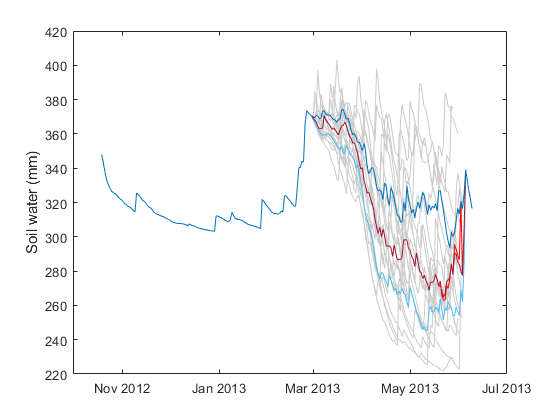

soil_water_stats = prctile(A,[25,50,75],2);
plot(T.date,soil_water_stats);

#### Create a histogram of grain yield distributions

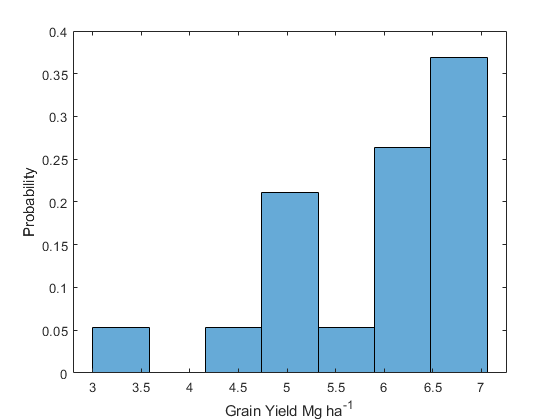

figure('Color','w')
nbins = 7;
histogram( [J.outputs.grainYield.y], nbins, 'Normalization','probability')
xlabel('Grain Yield Mg ha^{-1}')
ylabel('Probability')

Created by Andres Patrignani. Last updated 13-Nov-2020.